### Sound Analysis Lecture


clc;
clear;
close all;
%{
array = []

%{
x = audioread('12.ogg')
SIG=fft((x,1000)/length(x));
t = (0:999)

%}

    audio = audioread('1.ogg')
    SIG = fft(audio,1000)/length(audio);
    t = (0:999)  


%plot time domain signal
plot(t,SIG)
grid on
set(gca, 'FontName', 'Time New Romain', 'FontSize', 12)
xlabel('Time')
ylabel('Amp')
title('Signal')

%}

%{
[y,fs] = audioread('12.ogg')
y = y(:,1);
dt = 1/fs
t = 0:dt:(length(y)*dt)-dt;
plot(t,y); xlabel('Seconds'); ylabel('Amplitude'); 
title('Signal number 12');
%figure
%plot(psd(spectrum.periodogram,y,'Fs',fs,'NFFT',length(y)));


minimum = min(SIG)
maximum = max(SIG)
average = mean(SIG)
medianValue = median(SIG)
variance = var(SIG)
array(1) = average
array(2) = maximum
array(3) = minimum
array(4) = medianValue
array(5) = variance

snr = 1000
out = awgn(SIG , snr) 
plot(t,out)
grid on
set(gca, 'FontName', 'Time New Romain', 'FontSize', 12)
xlabel('Time is(s)')
ylabel('vol')
title('Noized Signal')

audiowrite('NoisySig.wav',out,1000);

load Filter3.mat

filtered_sig=conv(out,Num);
audiowrite('Filtered.wav',filtered_sig,t);

plot(t,filtered_sig)
grid on
set(gca, 'FontName', 'Time New Romain', 'FontSize', 12)
xlabel('Time is(s)')
ylabel('vol')
title('signal in time domain')



x = audioread('12.ogg')
SIG=fft(x/length(x));
t = length(x)
plot(t,SIG)

%}



snr = 50
[y,Fs] = audioread('13.ogg')
y = y(:,1);
dt = 1/ Fs
t = 0:dt:(length(y)*dt)-dt;
out = awgn(y , snr)
plot(t,out);
xlabel('Seconds');
ylabel('Amplitude'); 
title('Noisy signal number 13 (snr=50)');



load Filter5.mat

filtered_sig=conv(out,Filter);
t = (0:(length(filtered_sig)-1))
plot(t,filtered_sig);
xlabel('Seconds');
ylabel('Amplitude'); 
title('Filter Noisy signal number 13 (snr=50)');
%}



load Filter5.mat
snr = 50

snr = 50

x = audioread('13.ogg')

x =     0.0410
    0.0417
   -0.0142
    0.2360
    0.0552
    0.2186
    0.2874
    0.0997
    0.2927
   -0.0360


x = awgn(x , snr) 

x =     0.0020
    0.0047
    0.0036
    0.0013
   -0.0021
   -0.0029
   -0.0044
   -0.0009
   -0.0041
   -0.0012


x=conv(x,Filter);


SIG=fft(x,1000)/length(x);
t = (0:999)

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49




plot(t,SIG)

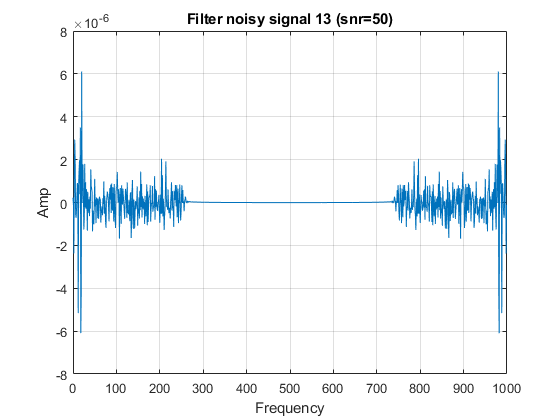

grid on
xlabel('Frequency');
ylabel('Amp'); 
title('Filter noisy signal 13 (snr=50)');





load 6.mat
snr = 50
x = audioread('1.ogg')
x = awgn(x , snr) 


%filtered_sig=conv(x,Filter);
%t = (0:(length(filtered_sig)-1))

SIG=fft(x,1000)/length(x);
t = (0:999)


plot(t,SIG)
grid on
xlabel('Frequency');
ylabel('Amp'); 
title('FFT noisy signal 13 (snr=50)');

%}


%{
plot(t,SIG)
xlabel('Frequency');
ylabel('Amp'); 
title('Filter FFT noisy signal 13 (snr=0)');
%}
